# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_5_Data_Analysys

## **Detrending Data**

Real-world data often contain **trends**—long-term movements, seasonal components, or other systematic patterns—that may obscure the underlying short-term fluctuations of interest.

**Detrending** is the process of removing these unwanted trends to better analyze residual behaviors such as cycles, volatility, or irregular variations.

In this activity, you will import a financial time series and explore how to isolate specific components by removing overall trends.

The **Find and Remove Trends** Live Editor Task allows you to perform detrending interactively, without manually writing code.

To insert it, go to **Live Editor Tab → Task → Add Task → Find and Remove Trends**, and then select the variable you want to detrend.

MATLAB automatically generates the corresponding code, which can be inspected, modified, and reused later in your analysis.

% Import data from spreadsheet
Data = readtimetable("C:\Users\mdolf\OneDrive\Documents\Didattica 2026\MATLAB\Codes\Data\Data Analysis\Data.xlsx", "RowTimes", "Date");

% Display results
Data

Data = 165×12 timetable
       Date         AAPL      MSFT      NVDA     GOOGL      GOOG      JPM        GS      HSBC      KO        PG       XOM      SHEL 
    ___________    ______    ______    ______    ______    ______    ______    ______    _____    _____    ______    ______    _____

    02-Jan-2025    243.85    418.58    138.31    189.43    190.63       240    574.97    48.68    61.84    165.98    107.31     63.1
    03-Jan-2025    243.36    423.35    144.47    191.79    193.13    243.28    580.13    49.07    61

Often data sets contain more than just a single trend but what if you are interested in analyzing only one of the trends. The process of removing unwanted trends in data is called *detrending*

APPL=Data.AAPL

APPL =   243.8500
  243.3600
  245.0000
  242.2100
  242.7000
  236.8500
  234.4000
  233.2800
  237.8700
  228.2600
  229.9800
  222.6400
  223.8300
  223.6600
  222.7800


In some applications, your data might display multiple features but you're only be interested in analyzing one of them. A variable might show a couple different features: a short-term, periodic oscillation, and a longer-term, increasing trend.

The **Find and Remove Trends** Live Editor task has been added to the live script for you.

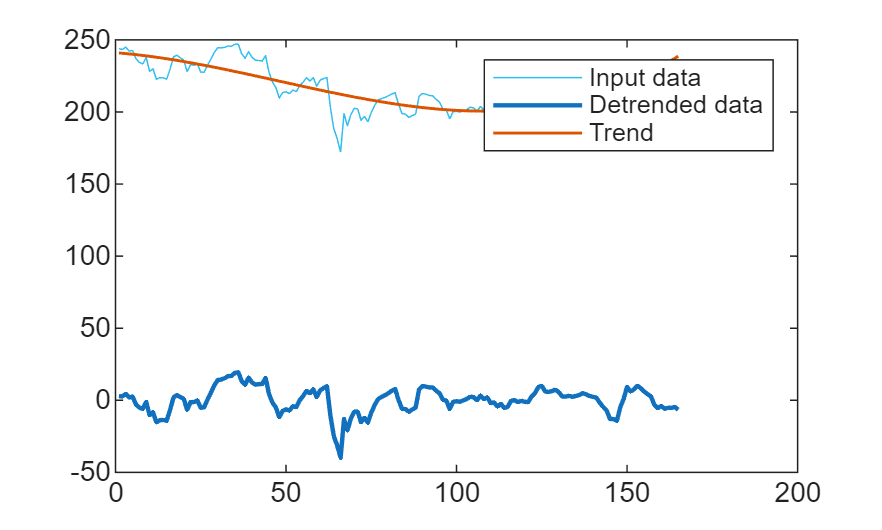

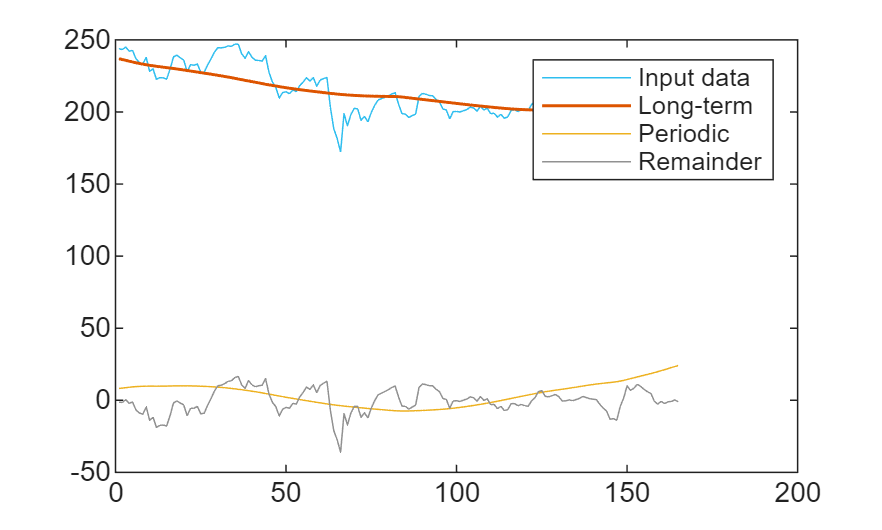

% Remove trend from input data
detrendedData = detrend(APPL,3);

% Display results
figure
plot(APPL,SeriesIndex=6,DisplayName="Input data")
hold on
plot(detrendedData,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(APPL-detrendedData,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend

The cubic trend does a much better job at capturing the underlying long-term trend in the data. You can clear the **Input data** and **Trend** from the **Display results** section to better see how well the data was detrended. Ideally, the data is "flattened" with only the short-term, periodic oscillations remaining.

However, sometimes the underlying trend in data is too complicated to be removed using simple polynomials. One portion of a data set might be perfectly detrended using only a linear trend, while other portions may not follow that same trend. In that case, you can set breakpoints to partition the data and detrend smaller portions individually. In the Live Editor task, try setting three equally spaced breakpoints to detrend the electricity usage data. You can change the **Polynomial Type** to see how it affects the detrended output.

Now the data set is ready to be analyzed. For example, you could try to extract some insights from the data by fitting a model to it, or pass it through a Fourier transform to look for periodicities.

**Note:**

Detrending is often an essential preprocessing step before performing correlation, regression, or spectral analyses.

Removing long-term trends helps make the data **stationary**, meaning that its statistical properties (mean and variance) remain stable over time.

Stationary data allow for more reliable interpretation of relationships between variables, as correlations and dependencies are not driven by shared trends but by genuine co-movements or fluctuations.